# NAGI 1b


RA = 274.654678;
DEC = 30.923869;

args =  struct(...
            'MagField', {{'MAG_APER_2'}}, ...
            'MagErrField', {{'MAGERR_APER_2'}}, ...
            'BadFlags', {{'Saturated', 'Negative', 'NaN', 'Spike', 'Hole', 'NearEdge'}}, ...
            'EdgeFlags', {{'Overlap'}}, ...
            'runMeanFilterArgs', {{'Threshold', 5, 'StdFun', 'OutWin'}}, ...
            'Nvisits', 2, ...
            'Ndet', 16*2 ...
        );

% Specify the paths for yout target
Paths = {'~/marvin/LAST.01.04.01/2024/09/01/proc';...
    '~/marvin/LAST.01.04.02/2024/09/01/proc';...
    '~/marvin/LAST.01.04.03/2024/09/01/proc';...  
    '~/marvin/LAST.01.04.04/2024/09/01/proc';...
    '~/marvin/LAST.01.05.01/2024/09/01/proc';...
    '~/marvin/LAST.01.05.02/2024/09/01/proc';...
    '~/marvin/LAST.01.05.03/2024/09/01/proc';...
    '~/marvin/LAST.01.05.04/2024/09/01/proc';...
    '~/marvin/LAST.01.01.01/2024/09/01/proc';...
    '~/marvin/LAST.01.02.01/2024/09/01/proc';...
    '~/marvin/LAST.01.03.01/2024/09/01/proc';...
    '~/marvin/LAST.01.06.01/2024/09/01/proc';...
    '~/marvin/LAST.01.10.01/2024/09/01/proc';...
    };



h = waitbar(0)

h =   Figure (TMWWaitbar) with properties:

      Number: []
        Name: ''
       Color: [0.96078 0.96078 0.96078]
    Position: [576 453 360 75]
       Units: 'points'

  Show all properties

Paths = 1×2 cell array
    {'~/marvin/LAST.01.04.02/2024/09/01/proc'}    {[15]}

Paths = 2×2 cell array
    {'~/marvin/LAST.01.04.02/2024/09/01/proc'}    {[15]}
    {'~/marvin/LAST.01.04.02/2024/09/01/proc'}    {[16]}

P = 2×2 cell array
    {'~/marvin/LAST.01.04.02/2024/09/01/proc'}    {[15]}
    {'~/marvin/LAST.01.04.02/2024/09/01/proc'}    {[16]}

MSU =   MatchedSources with properties:

              Data: [1×1 struct]
             Units: [1×1 struct]
                JD: [780×1 double]
           SrcData: [1×1 struct]
          FileName: []
            Fields: {21×1 cell}
              Nsrc: 2385
            Nepoch: 780
          DimEpoch: 1
            DimSrc: 2
         DefNamesX: {'X'  'X_IMAGE'  'XWIN_IMAGE'  'X1'  'X_PEAK'  'XPEAK'}
         DefNamesY: {'Y'  'Y_IMAGE'  'YWIN_IMAGE'  'Y1'  'Y_PEAK'  'YPEAK'}
        DefNamesRA: {'RA'  'ALPHA'  'ALPHAWIN_J2000'  'ALPHA_J2000'  'RA_J2000'  'RAJ2000'  'RightAsc'}
       DefNamesDec: {'Dec'  'DEC'  'DELTA'  'DELTAWIN_J2000'  'DELTA_J2000'  'DEC_J2000'  'DEJ2000'  'Declination'}
     DefNamesErrRA: {'RAERR'  'RA_ERR'  'ALPHAERR'  'ALPHA_ERR'}
    DefNamesErrDec: {'DecErr'  'DECERR'  'DEC_ERR'  'DELTAERR'  'DELTA_ERR'}
       DefNamesMag: {'Mag'  'PSF_MAG'  'MAG_PSF'  'Mag_BP'  'Mag_G'  'Mag_RP'  'MAG_CONV_

MSU =   MatchedSources with properties:

              Data: [1×1 struct]
             Units: [1×1 struct]
                JD: [780×1 double]
           SrcData: [1×1 struct]
          FileName: []
            Fields: {21×1 cell}
              Nsrc: 2566
            Nepoch: 780
          DimEpoch: 1
            DimSrc: 2
         DefNamesX: {'X'  'X_IMAGE'  'XWIN_IMAGE'  'X1'  'X_PEAK'  'XPEAK'}
         DefNamesY: {'Y'  'Y_IMAGE'  'YWIN_IMAGE'  'Y1'  'Y_PEAK'  'YPEAK'}
        DefNamesRA: {'RA'  'ALPHA'  'ALPHAWIN_J2000'  'ALPHA_J2000'  'RA_J2000'  'RAJ2000'  'RightAsc'}
       DefNamesDec: {'Dec'  'DEC'  'DELTA'  'DELTAWIN_J2000'  'DELTA_J2000'  'DEC_J2000'  'DEJ2000'  'Declination'}
     DefNamesErrRA: {'RAERR'  'RA_ERR'  'ALPHAERR'  'ALPHA_ERR'}
    DefNamesErrDec: {'DecErr'  'DECERR'  'DEC_ERR'  'DELTAERR'  'DELTA_ERR'}
       DefNamesMag: {'Mag'  'PSF_MAG'  'MAG_PSF'  'Mag_BP'  'Mag_G'  'Mag_RP'  'MAG_CONV_

Paths = 1×2 cell array
    {'~/marvin/LAST.01.04.03/2024/09/01/proc'}    {[9]}

P = 1×2 cell array
    {'~/marvin/LAST.01.04.03/2024/09/01/proc'}    {[9]}

LC =[];
for Ipth = 2 : numel(Paths)


        P = findTargetInPath(Paths{Ipth},RA,DEC)
    for Ip = 1:height(P)
        pathToDir = P{Ip,1}  ;
        CropID = P{Ip,2};
        MSU = getMS(pathToDir,CropID)
        MMS = MSU.setBadPhotToNan('BadFlags',args.BadFlags, 'MagField',args.MagField{:}, 'CreateNewObj',true);
        
        % Remove sources with NdetGood<MinNdet
        NdetGood = sum(~isnan(MMS.Data.(args.MagField{:})), 1);
        Fndet    = NdetGood>17;
        Result.Ndet     = sum(Fndet);


        % good stars found

        MMS      = MMS.selectBySrcIndex(Fndet, 'CreateNewObj',false);
            
%%
 
       % MMS.sysrem('MagFields' ,{'MAG_APER_3'} , 'MagErrFields',{'MAGERR_APER_3'},'sysremArgs',{'Niter',2});

        ind = MMS.coneSearch(RA,DEC,4).Ind;
        if ~isempty(ind)
            lcData = getLCdata(MMS,RA,DEC,args);
            lc =lcData{1};
            figure();
            plot(lc.JD,lc.relFlux,'-ok')
            title(sprintf('%s CROPID #%i',Paths{Ipth},CropID))
        else
            fprintf('Cant find source in %s',pathToDir)
        end
        
        LC = [LC; lcData];
        
        waitbar(Ipth/numel(Paths),h,sprintf('%i/%i Paths have been processed',Ipth,numel(Paths)))
    end
end

lcdat = struct with fields:
           Ind: 2124
        Coords: [274.65 30.924]
            JD: [780×1 double]
            lc: [780×1 double]
         lcErr: [780×1 double]
     typicalSD: 0.024231
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [780×1 double]
    relFluxErr: [780×11 double]
    typScatter: 0.01907

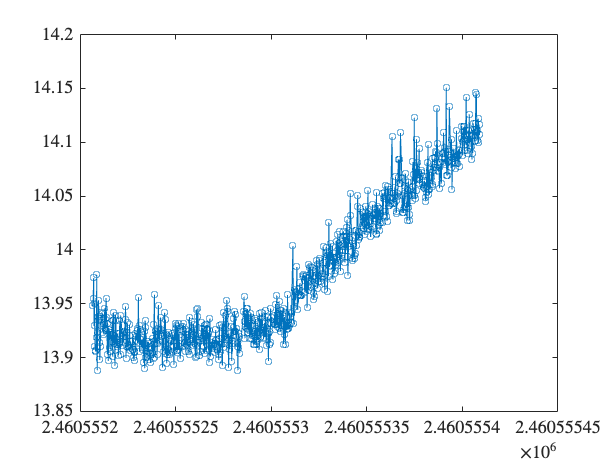

lcdat = struct with fields:
           Ind: 86
        Coords: [274.65 30.924]
            JD: [780×1 double]
            lc: [780×1 double]
         lcErr: [780×1 double]
     typicalSD: 0.036764
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [780×1 double]
    relFluxErr: [780×14 double]
    typScatter: 0.024341

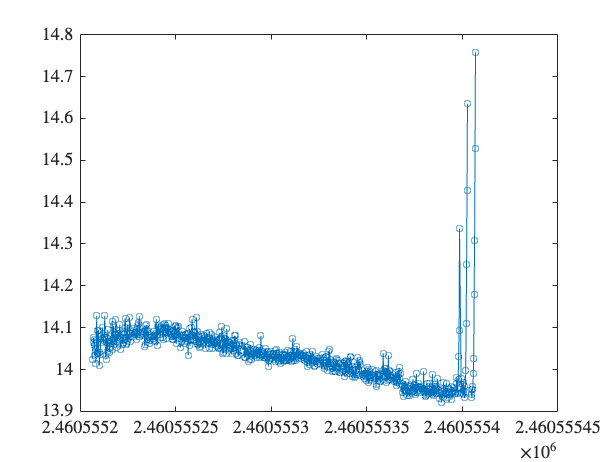

lcdat = struct with fields:
           Ind: 2296
        Coords: [274.65 30.924]
            JD: [780×1 double]
            lc: [780×1 double]
         lcErr: [780×1 double]
     typicalSD: 0.033879
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [780×1 double]
    relFluxErr: [780×10 double]
    typScatter: 0.021047

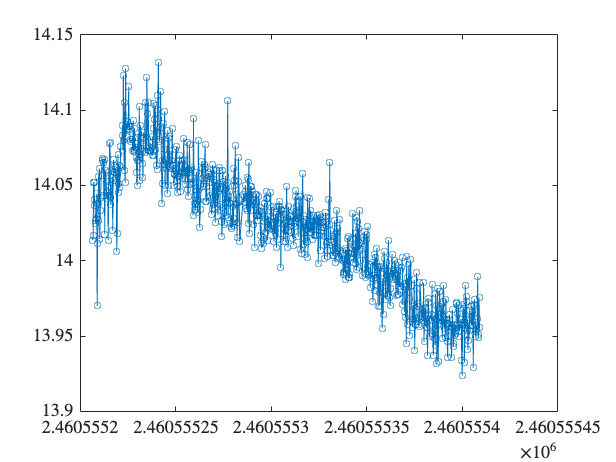

lcdat = struct with fields:
           Ind: 2064
        Coords: [274.65 30.924]
            JD: [780×1 double]
            lc: [780×1 double]
         lcErr: [780×1 double]
     typicalSD: 0.035135
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [780×1 double]
    relFluxErr: [780×10 double]
    typScatter: 0.021828

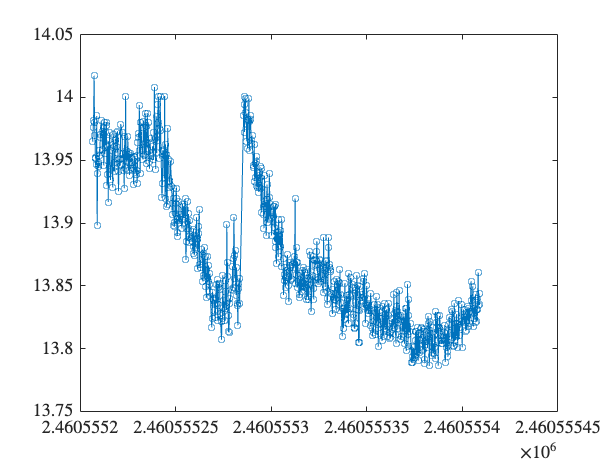

lcdat = struct with fields:
           Ind: 2165
        Coords: [274.65 30.924]
            JD: [780×1 double]
            lc: [780×1 double]
         lcErr: [780×1 double]
     typicalSD: 0.070504
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [780×1 double]
    relFluxErr: [780×11 double]
    typScatter: 0.058613

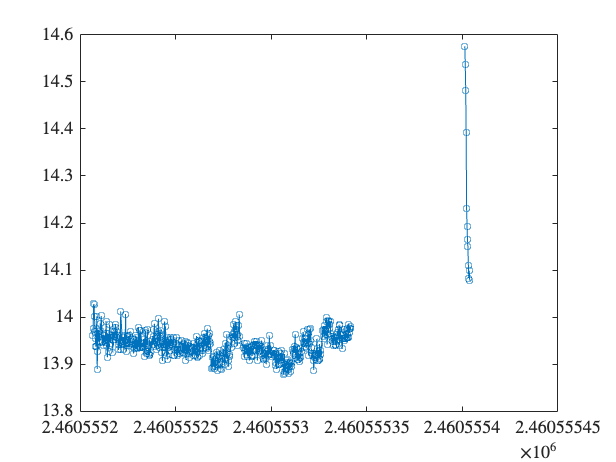

lcdat = struct with fields:
           Ind: 344
        Coords: [274.65 30.924]
            JD: [760×1 double]
            lc: [760×1 double]
         lcErr: [760×1 double]
     typicalSD: 0.04693
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [760×1 double]
    relFluxErr: [760×10 double]
    typScatter: 0.03094

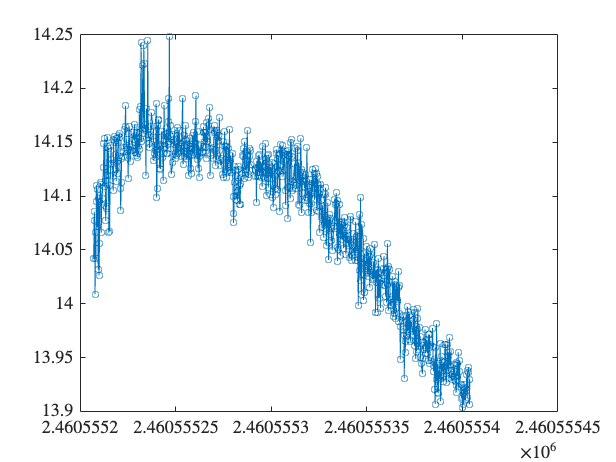

lcdat = struct with fields:
           Ind: 342
        Coords: [274.65 30.924]
            JD: [720×1 double]
            lc: [720×1 double]
         lcErr: [720×1 double]
     typicalSD: 0.021278
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [720×1 double]
    relFluxErr: [720×11 double]
    typScatter: 0.020204

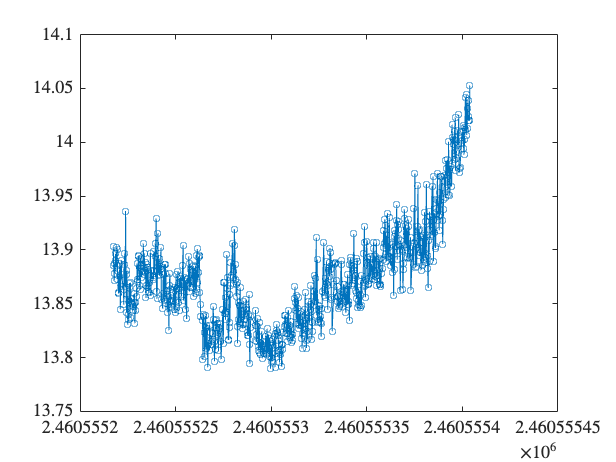

lcdat = struct with fields:
           Ind: 359
        Coords: [274.65 30.924]
            JD: [720×1 double]
            lc: [720×1 double]
         lcErr: [720×1 double]
     typicalSD: 0.028152
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [720×1 double]
    relFluxErr: [720×14 double]
    typScatter: 0.031842

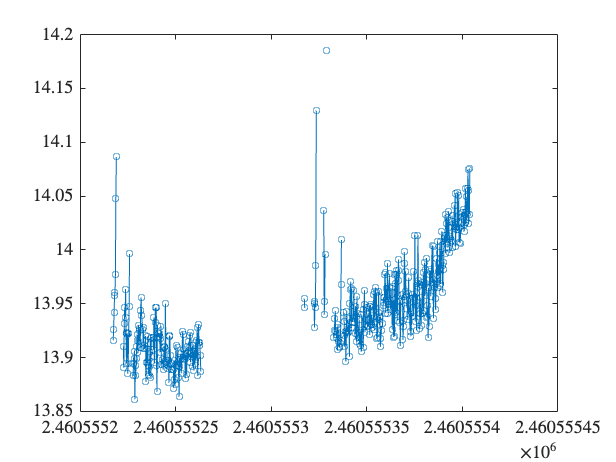

lcdat = struct with fields:
           Ind: 2708
        Coords: [274.65 30.924]
            JD: [760×1 double]
            lc: [760×1 double]
         lcErr: [760×1 double]
     typicalSD: 0.025678
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [760×1 double]
    relFluxErr: [760×12 double]
    typScatter: 0.01944

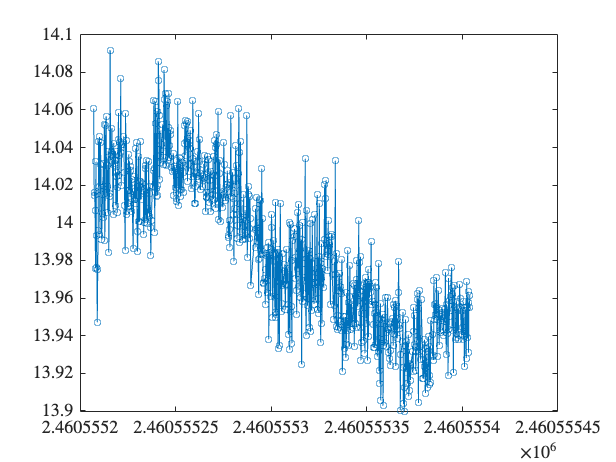

lcdat = struct with fields:
           Ind: 115
        Coords: [274.65 30.924]
            JD: [760×1 double]
            lc: [760×1 double]
         lcErr: [760×1 double]
     typicalSD: 0.023618
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [760×1 double]
    relFluxErr: [760×10 double]
    typScatter: 0.021755

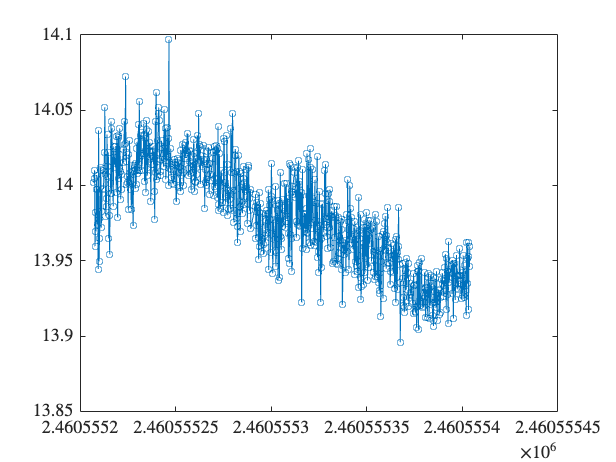

lcdat = struct with fields:
           Ind: 1791
        Coords: [274.65 30.924]
            JD: [760×1 double]
            lc: [760×1 double]
         lcErr: [760×1 double]
     typicalSD: 0.027111
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [760×1 double]
    relFluxErr: [760×10 double]
    typScatter: 0.018594

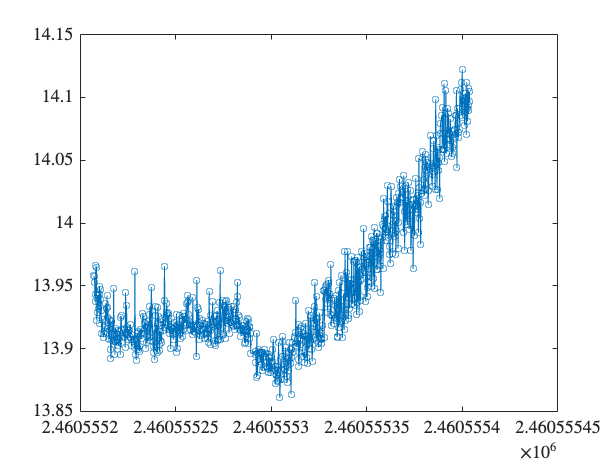

lcdat = struct with fields:
           Ind: 679
        Coords: [274.65 30.924]
            JD: [660×1 double]
            lc: [660×1 double]
         lcErr: [660×1 double]
     typicalSD: 0.013294
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [660×1 double]
    relFluxErr: [660×11 double]
    typScatter: 0.015532

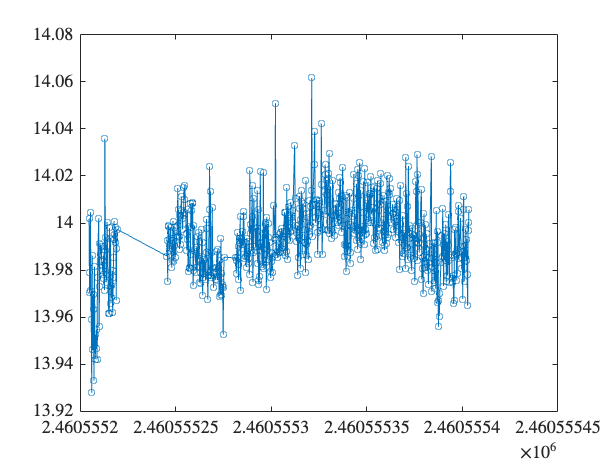

lcdat = struct with fields:
           Ind: 751
        Coords: [274.65 30.924]
            JD: [724×1 double]
            lc: [724×1 double]
         lcErr: [724×1 double]
     typicalSD: 0.017067
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [724×1 double]
    relFluxErr: [724×10 double]
    typScatter: 0.017253

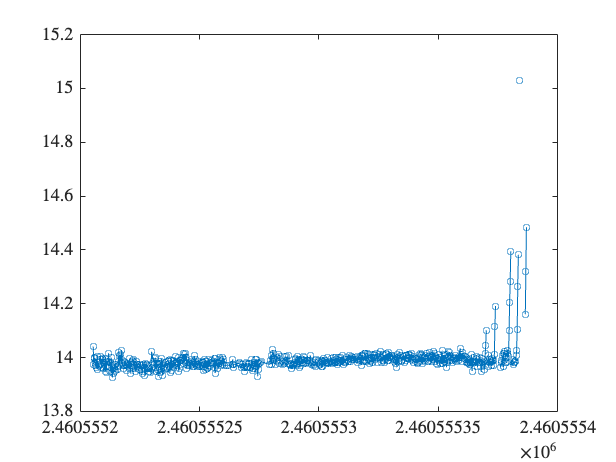

lcdat = struct with fields:
           Ind: 732
        Coords: [274.65 30.924]
            JD: [724×1 double]
            lc: [724×1 double]
         lcErr: [724×1 double]
     typicalSD: 0.020655
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [724×1 double]
    relFluxErr: [724×11 double]
    typScatter: 0.017126

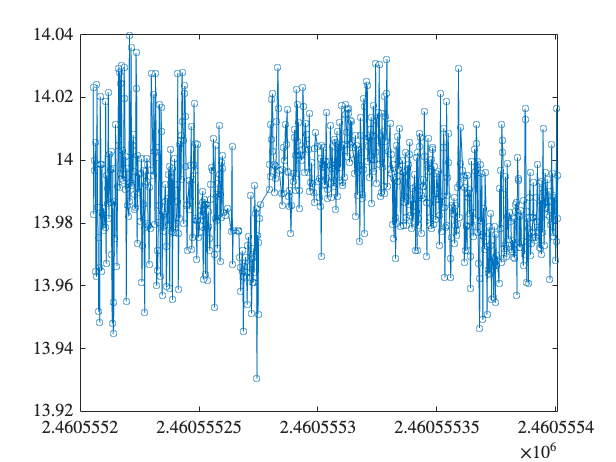

lcdat = struct with fields:
           Ind: 299
        Coords: [274.65 30.924]
            JD: [760×1 double]
            lc: [760×1 double]
         lcErr: [760×1 double]
     typicalSD: 0.026728
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [760×1 double]
    relFluxErr: [760×10 double]
    typScatter: 0.022121

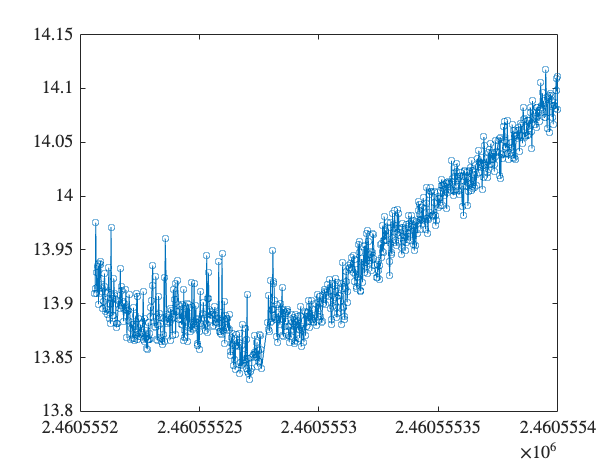

lcdat = struct with fields:
           Ind: 303
        Coords: [274.65 30.924]
            JD: [760×1 double]
            lc: [760×1 double]
         lcErr: [760×1 double]
     typicalSD: 0.039366
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [760×1 double]
    relFluxErr: [760×13 double]
    typScatter: 0.036282

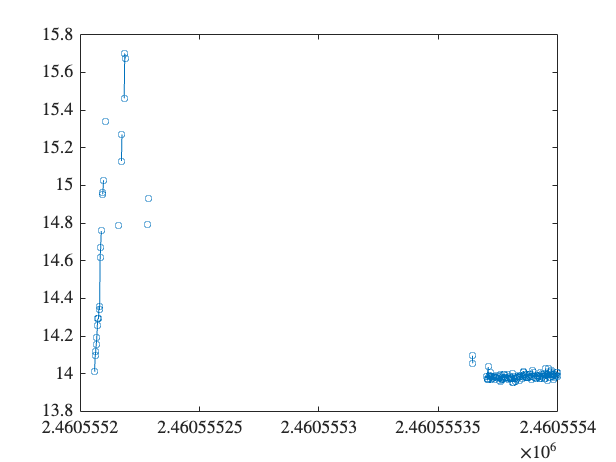

lcdat = struct with fields:
           Ind: 985
        Coords: [274.65 30.924]
            JD: [680×1 double]
            lc: [680×1 double]
         lcErr: [680×1 double]
     typicalSD: 0.028313
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [680×1 double]
    relFluxErr: [680×11 double]
    typScatter: 0.020982

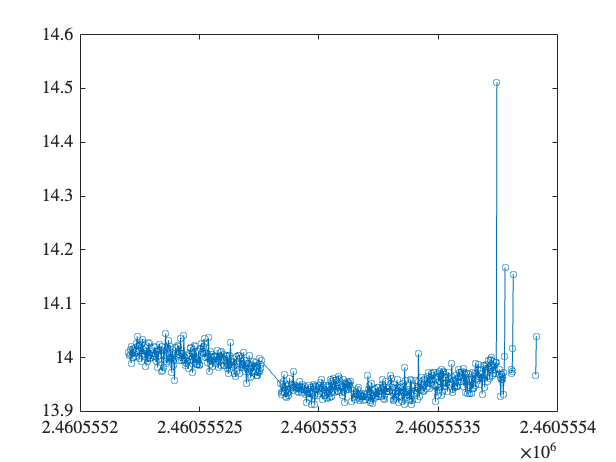

lcdat = struct with fields:
           Ind: 735
        Coords: [274.65 30.924]
            JD: [760×1 double]
            lc: [760×1 double]
         lcErr: [760×1 double]
     typicalSD: 0.018841
         Flags: [1×1 struct]
          Ctrl: [1×1 struct]
       relFlux: [760×1 double]
    relFluxErr: [760×10 double]
    typScatter: 0.01468

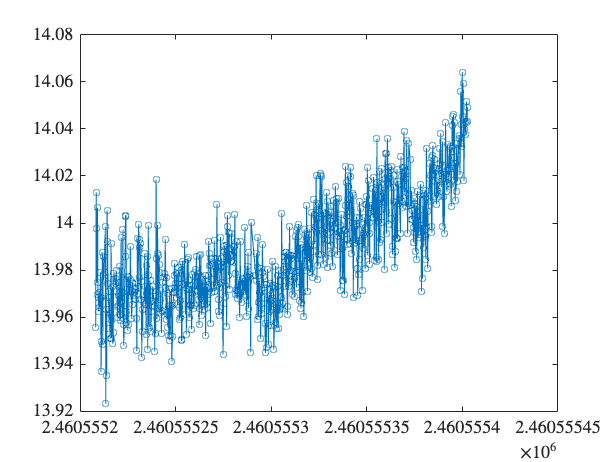

for Ilc = 1:numel(LC)
        lcdat = LC{Ilc}
        figure();
        plot(lcdat.JD,lcdat.lc,'-o')
        %title(Paths(Ilc))

        
end

## Functions

function lcData = getLCdata(MSU,RA,Dec,args)
    Ibatch = 1;
    lcData{Ibatch} = struct();

    mms = MSU.setBadPhotToNan('BadFlags', args.BadFlags, 'MagField', 'MAG_PSF', 'CreateNewObj', true);
    r = lcUtil.zp_meddiff(MSU, 'MagField', args.MagField, 'MagErrField', args.MagErrField);
    [mms, ~] = applyZP(MSU, r.FitZP, 'ApplyToMagField', args.MagField);


    lcData{Ibatch} = WDtransits1.extractLightCurve(lcData{Ibatch}, mms,  RA,Dec,args);
    
   % lcData{Ibatch} = WDtransits1.handleNaNValues(lcData{Ibatch},mms, mms.Nepoch);
    %[~,fname,~] = fileparts(batch{Ibatch}(Ivis).FileName);
    %part = strsplit(fname,'_');
    %lcData{Ibatch}.Tel = part{1};
    %lcData{Ibatch}.Date = part{2};
                
            
    %lcData{Ibatch}.Table.RA = Table.RA;
    %lcData{Ibatch}.Table.Dec = Table.Dec;
    %lcData{Ibatch}.Table.Gmag = 1;
    %lcData{Ibatch}.Table.Total_Visits = Table.Nvisits;
    %lcData{Ibatch}.Table.Visits_Found= length(batch) ;
    %lcData{Ibatch}.Table.Subframe = Table.CropID;
    %lcData{Ibatch}.Table.Name = Table.Name;

end

function MSU = getMS(pathToDir,CropID)
    
     cd(pathToDir)
     List = MatchedSources.rdirMatchedSourcesSearch('CropID',CropID);
     MS = MatchedSources.readList(List);
     MSU = MS.mergeByCoo(MS(1));
     

end

function Paths = findTargetInPath(Path,RA,Dec,args)
        % Must initilize the path for the LAST visits catalog
        cd(Path);
        Dirs = dir;
        cd(Dirs(3).name)
        Paths = [];

        for i = 1 :24
            List = MatchedSources.rdirMatchedSourcesSearch('CropID',i);
            MS = MatchedSources.readList(List);
            ind = MS.coneSearch(RA,Dec,4).Ind;
            if ~isempty(ind)
                Paths = [Paths ; {Path , i}]
            end

           
        end
            

   

end